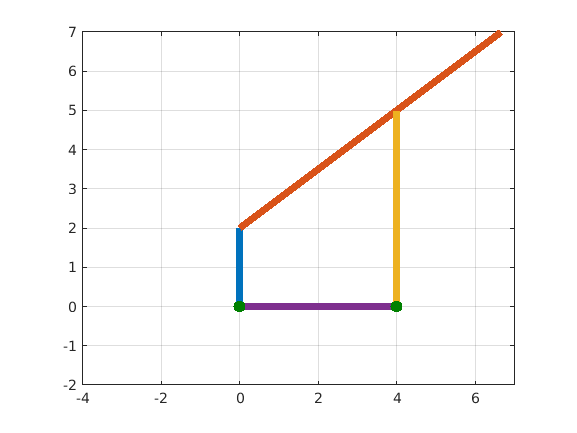

clc;
clear all;
close all;
l2= 2;
l1=2*l2;
l3 = 2.5*l2; 
l4 = 2.5*l2;
theta1 = 0:1:360;
for i= 1:length(theta1)
lac(i) = l2*sqrt(5+4*sind(theta1(i)));
loa1(i) = l2*(cosd(theta1(i))+sind(theta1(i)));
gamma(i) = acosd((1/5)*(sqrt(5+4*sind(theta1(i)))));
lpc(i)= 2*l2*sqrt(5-sind(theta1(i)));
alpha(i) = acosd((2+ sind(theta1(i)))/sqrt(5+4*sind(theta1(i))));
X(i) = 2*l2 + (2*l2*(sqrt(5-sind(theta1(i))))*(cosd(theta1(i))))/(sqrt(5+4*sind(theta1(i))));
Y(i) =  (2*l2*((sqrt(5-sind(theta1(i))))*(2+sind(theta1(i)))))/(sqrt(5+4*sind(theta1(i))));
lambda(i) = 90;
theta3(i)= asind(((2+sind(theta1(i))))/(sqrt(5+4*sind(theta1(i)))));
theta4(i)= 180 - 90 - alpha(i);
%define joint positions
ox(i)=0;
oy(i)=0;


ax(i)= ox(i)+l2*cosd(theta1(i)+90);
ay(i)= oy(i)+l2*sind(theta1(i)+90);

bx(i) = ox(i)+ax(i)+ l3*cosd(theta3(i));
by(i) = oy(i)+ay(i)+ l3*sind(theta3(i));

cx(i) = l1;
cy(i) = 0;

xb(i) = l2+ (l2*(sqrt(5-sind((theta1(i))))*(cosd(theta1(i))))/(sqrt(5+4*sind(theta1(i))))) - 1/2*l2*sind(theta1(i));
yb(i) = (l2*((sqrt(5-sind(theta1(i))))*(2+sind(theta1(i)))))/(sqrt(5+4*sind(theta1(i))))+ 1/2*l2*cosd(theta1(i));
 
plot([ox(i) ax(i)] , [oy(i) ay(i)] , [ax(i) X(i)] , [ay(i) Y(i)] ,[xb(i) cx(i)] , [yb(i) cy(i)] ,[cx(i) ox(i)] , [cy(i) oy(i)] , 'LineWidth',5)

xlim([-4.00 7.00])
ylim([-2.00 7.00])

hold on
plot(ox(i),oy(i),'.','MarkerSize',30,'color',[0, 0.5, 0]);
hold on
plot(cx(i),cy(i),'.','MarkerSize',30,'color',[0, 0.5, 0]);
hold on
plot(X,Y,'color',[0, 0, 1]);
hold on
grid on;
axis equal;
axis([-4 7 -2 7]);
pause(0.005);
hold off;


end

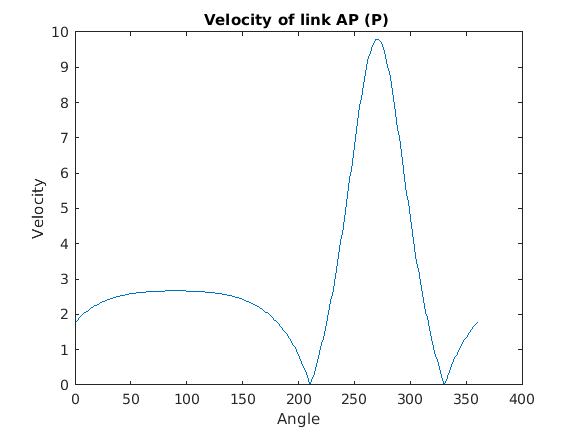



syms theta1
f = lpc;
lpd = diff(f);   % differentiation of lpc
lpd(361)=-0.095;
lpd2 = diff(diff(f));
lpd2(361)=-0.095;
f1 = theta3;
dtheta3 = diff(f1);
dtheta3(361)=0.2;
ddtheta3 = diff(diff(f1));
ddtheta3(361)=0.2;
Vpx = (lpd.*cosd(theta3)) - (lpc.*dtheta3.*sind(theta3));
Vpy = (lpd.*sind(theta3)) + (lpc.*dtheta3.*cosd(theta3));
V = sqrt(Vpx.^2+Vpy.^2);
A = ddtheta3.*lpc+ dtheta3.*(dtheta3.*lpc) + lpd2.*(cosd(theta3)+sind(theta3));
plot(V)

title('Velocity of link AP (P) ')
ylabel("Velocity")
xlabel("Angle")

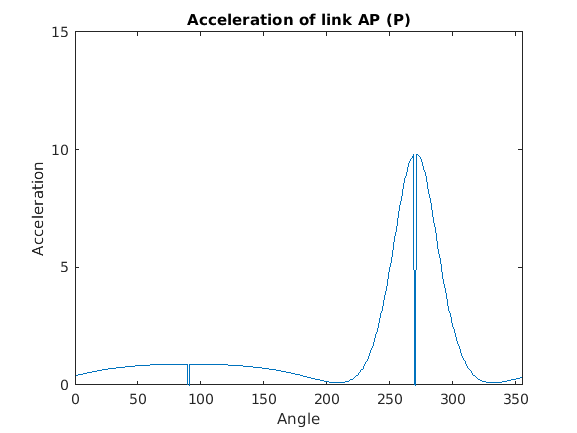

plot(A)
title('Acceleration of link AP (P)')
ylabel("Acceleration")
xlabel("Angle")
ylim([0,15])
xlim([0,355])

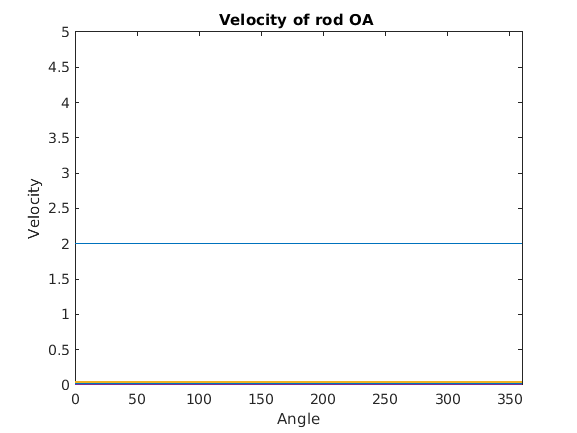



figure;

syms theta1
f = loa1;
loa = diff(f);   % differentiation of lpc
loa(361)=0;
loa2 = diff(loa); 
loa2(361)=0;
f1 = theta1;
dtheta1 = diff(f1);
dtheta1(361)=0;
ddtheta1 = diff(dtheta1);
ddtheta1(361)=0;
Vpx = (loa.*cosd(theta1)) - (loa1.*dtheta1.*sind(theta1));
Vpy = (loa.*sind(theta1)) + (loa1.*dtheta1.*cosd(theta1));
V = sqrt(Vpx.^2+Vpy.^2);
fplot(V)
title('Velocity of rod OA ')
ylabel("Velocity")
xlabel("Angle")
xlim([0 360])
ylim([0 5])

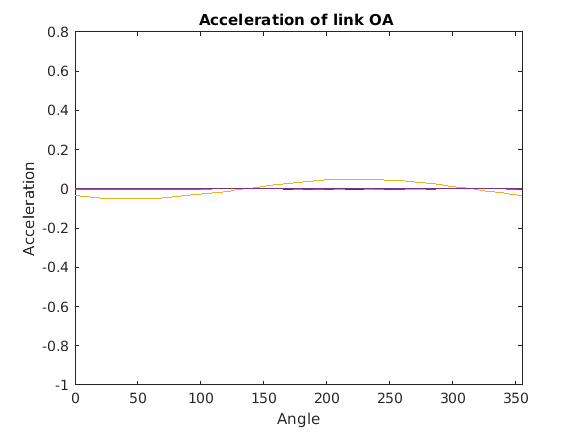


A = ddtheta1.*loa1+ dtheta1.*(dtheta1.*loa1) + loa2.*(cosd(theta1)+sind(theta1));
fplot(A)
title('Acceleration of link OA ')
ylabel("Acceleration")
xlabel("Angle")
ylim([-1,0.8])
xlim([0,355])